Step1:

shakey = read_image('', 'shakey.150.gif');
% help read_image
show_image(shakey, false);

load sobel.mat
% who
sobelX

sobelX =     -1     0     1
    -2     0     2
    -1     0     1


sobelY

sobelY =      1     2     1
     0     0     0
    -1    -2    -1


Task1:

i = 1

d = 10000

mean_last = 51.5307

new_im = 	1.0e+03 *

    1.0776    1.0160    1.0160    1.0160    1.0160    1.0160    1.0160    1.0140    1.0100    1.0080    1.0080    1.0080    1.0080    1.0080    1.0080    0.9966    0.9870    0.9941    0.9631    0.8304    0.6165    0.5170    0.4941    0.4756    0.4389    0.4328    0.4481    0.4600    0.4593    0.4387    0.4014    0.3626    0.3156    0.2701    0.2472    0.2439    0.2506    0.2505    0.2382    0.2240    0.2284    0.2276    0.2177    0.2093    0.2060    0.2093    0.2163    0.2200    0.2181    0.2160
    1.0160         0         0         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0460    0.0110    0.0214    0.2657    0.4331    0.3025    0.0968    0.0416    0.0781    0.0498    0.0253    0.0496    0.0344    0.0215    0.0756    0.0864    0.1057    0.1085    0.0850    0.0514    0.0142    0.0184    0.0240    0.0413    0.0045    0.0150    0.0200    0.0204    0.0148    0.0071    0.0126    0.0140    0.00

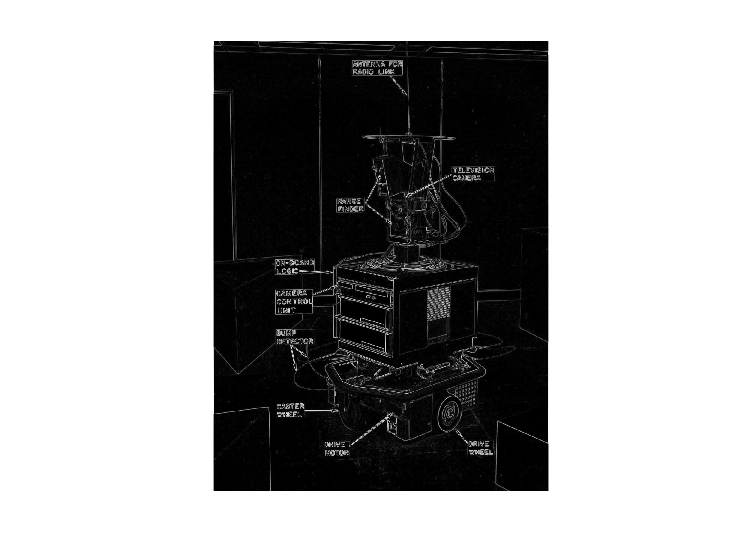

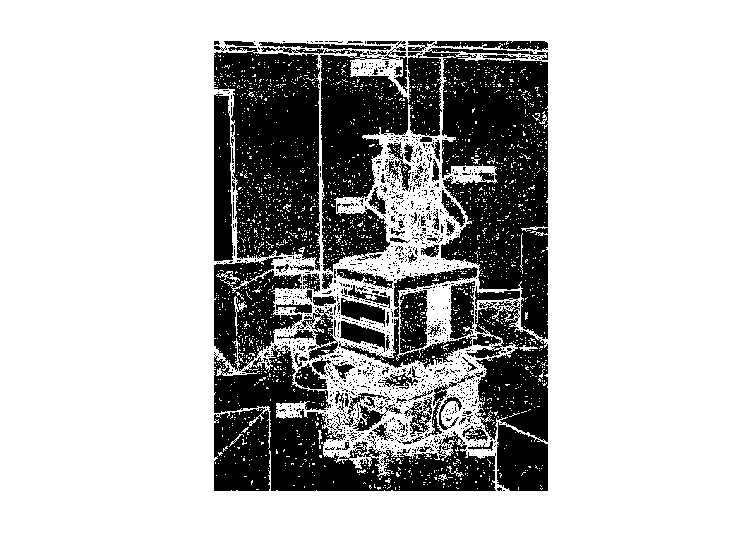

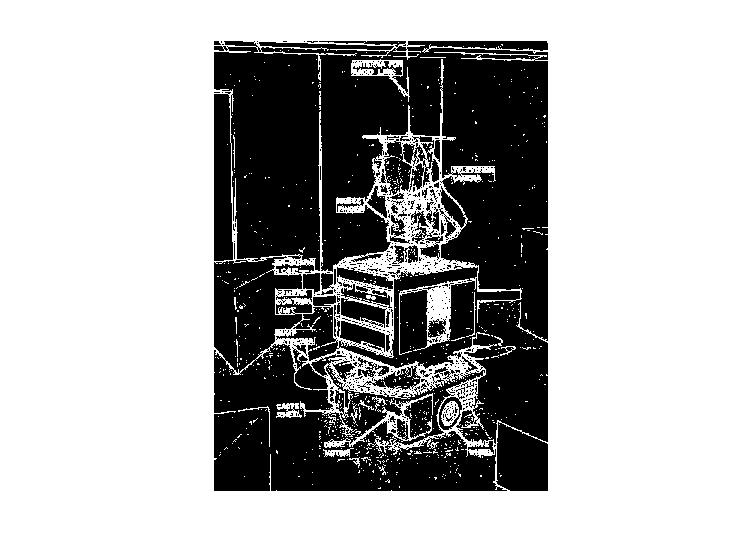

i = 2

d = 76.0616

mean_last = 127.5923

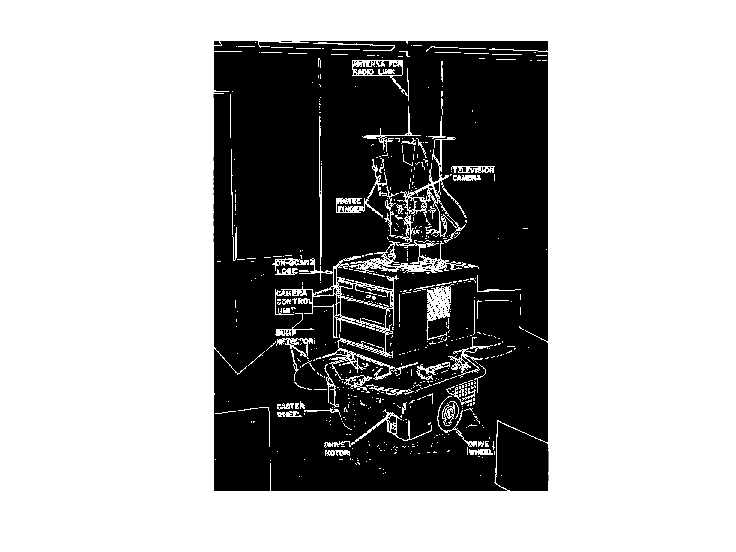

i = 3

d = 64.0562

mean_last = 191.6484

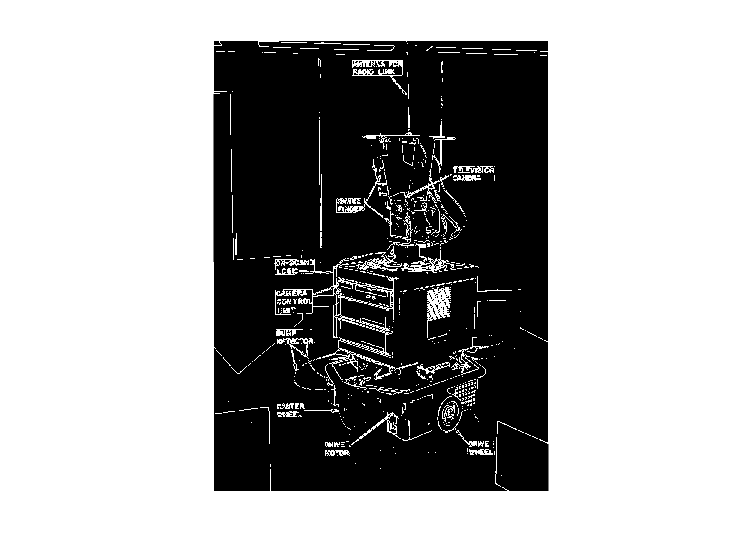

i = 4

d = 34.1603

mean_last = 225.8087

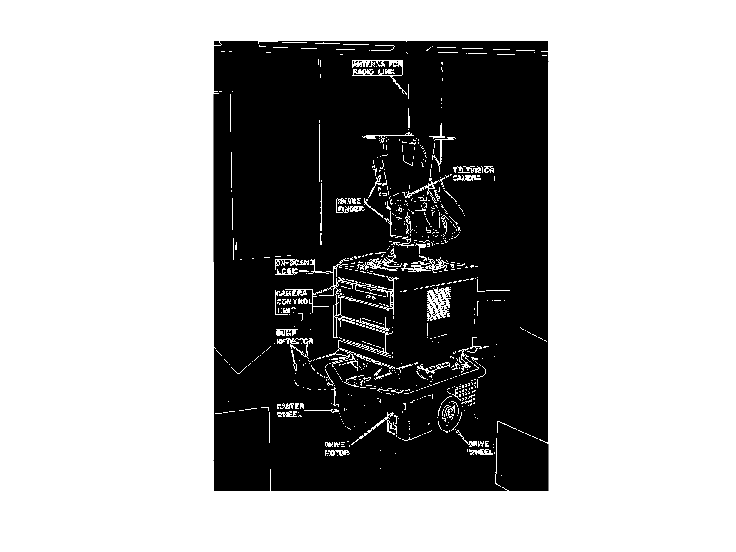

im_sol = task1(shakey, sobelX, sobelY, 0, 50, 'sobel-'); 

**QUESTION 1: What do you notice regarding the effect of changing the threshold? **

**when the threshold is too small, there's not much useful information. ( At least not to human eye)**

**when the threshold reaches around the mean of the image, the edges become clearer.**

**when the threshold gets larger. The edges get rblury.**

Task2:

load roberts.mat;
robertsA

robertsA =      0     1
    -1     0


robertsB

robertsB =     -1     0
     0     1


i = 1

d = 10000

mean_last = 10.8170

new_im =          0         0         0         0         0         0         0    2.8284         0         0         0         0         0         0         0   16.2788   20.5183   23.7065   87.8180   71.3092   16.1245    5.0990   11.1803   25.4951    6.7082   10.7703    7.0711    3.1623   12.0830   16.1555   11.1803   28.3019   14.0357   11.0000    4.1231    6.4031    3.1623    8.6023    9.2195    9.8995    3.6056    4.2426    3.6056    2.0000    2.2361    2.8284    2.8284    2.8284         0         0
         0         0         0         0         0         0         0    2.8284         0         0         0         0         0         0         0   16.2788   19.7990   10.1980   67.0671   82.0000   46.5296   12.8062    9.2195   14.1421    3.1623    6.7082   12.1655    6.3246    8.0000   17.7200   16.1555   19.6469   18.2483   17.0000    7.0711    2.2361    4.2426    6.0828    6.4031    7.2111    2.8284    3.6056    3.1623    2.0000    2.0000    2.2361    2.2361    2.2361         0

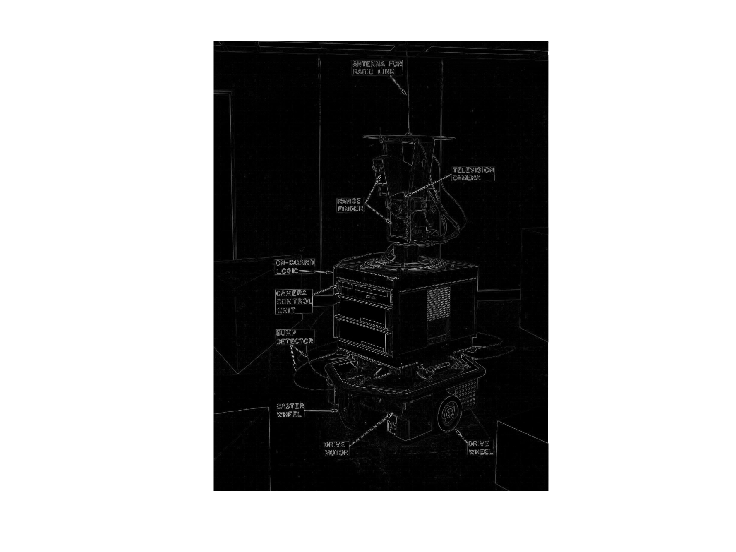

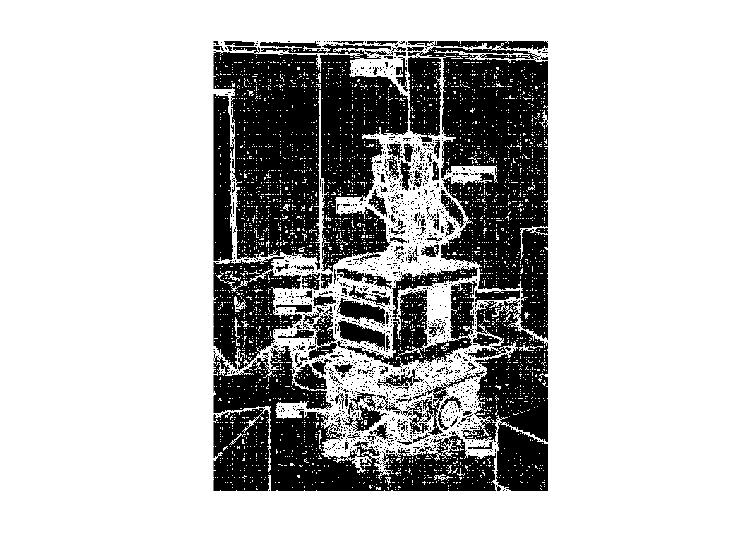

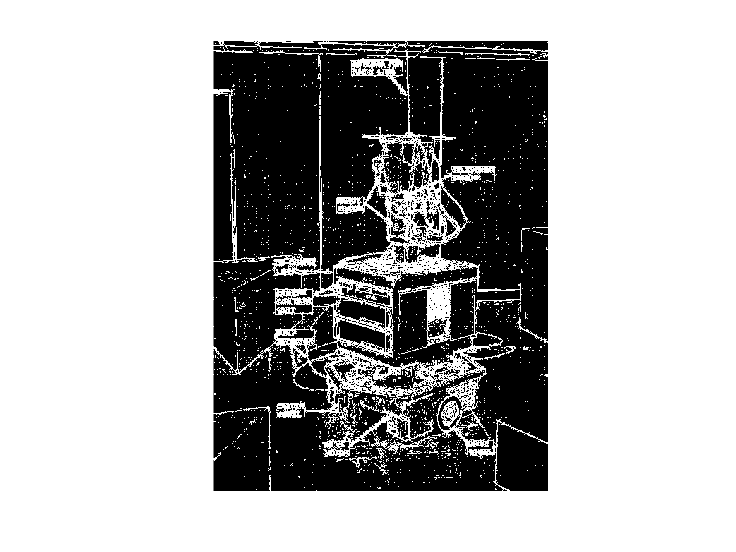

i = 2

d = 14.4990

mean_last = 25.3160

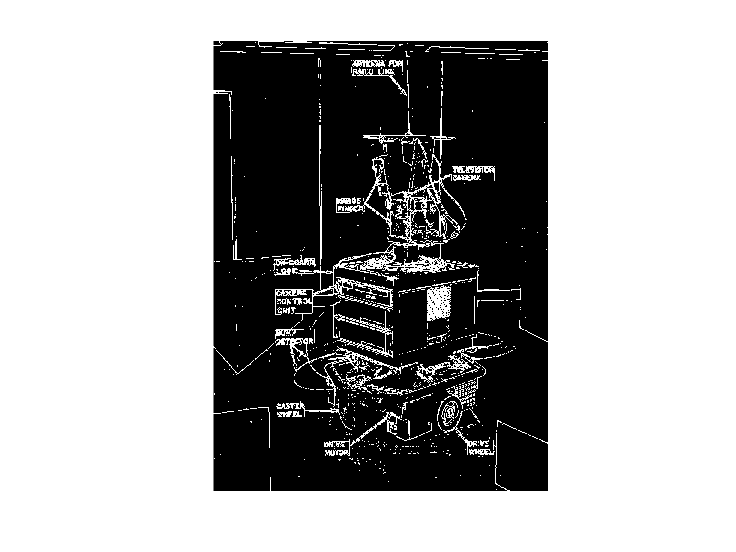

i = 3

d = 15.1836

mean_last = 40.4996

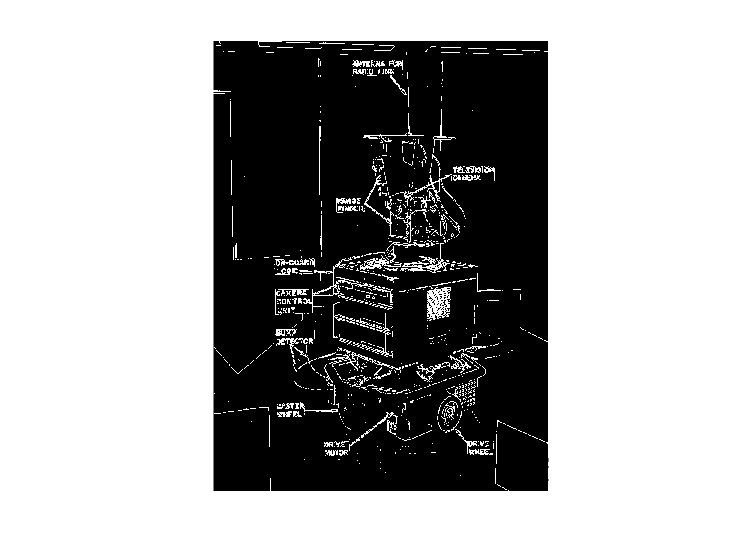

i = 4

d = 9.8797

mean_last = 50.3793

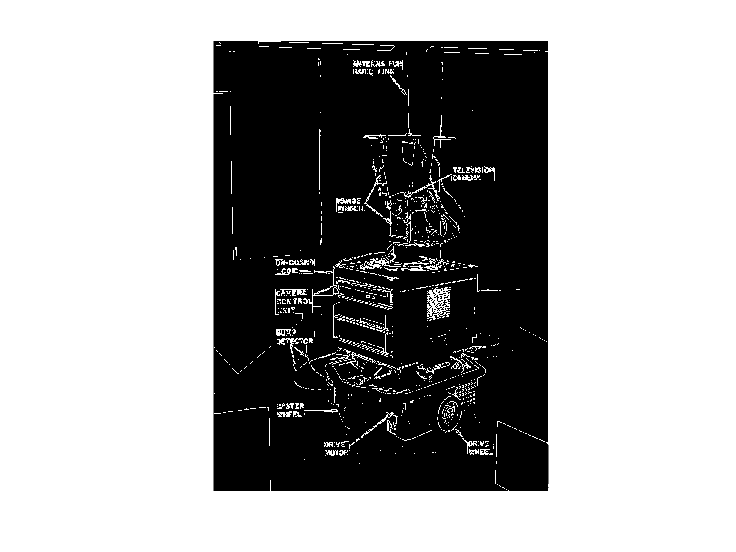


% task1(shakey, sobelX, sobelY, -1, 10, 'sobel-x-');
% task1(shakey, sobelX, sobelY, -2, 10, 'sobel-y-');
im_rob = task1(shakey, robertsA, robertsB, 0, 10, 'roberts-');

% task1(shakey, robertsA, robertsB, -1, 10, 'roberts-x-');
% task1(shakey, robertsA, robertsB, -2, 10, 'roberts-y-');

**QUESTION 2: What do you notice regarding the difference between Sobel and Roberts?**

**roberts produce more grid like noises in general because sobel is 3*3 so can preserve more.**

Task3:

i = 1

d = 10000

mean_last = 61.5844

new_im =         1524        1016        1016        1016        1016        1016        1016        1020        1016        1008        1008        1008        1008        1008        1008        1030         996        1004        1172        1088         748         520         506         548         478         470         478         460         492         492         450         436         386         302         256         264         268         266         274         226         242         244         234         220         208         220         228         220         224         216
        1016           0           0           0           0           0           0           8           8           0           0           0           0           0           0          46          12          30         340         570         416         134          58          94          58          32          70          48          28         102         114         136      

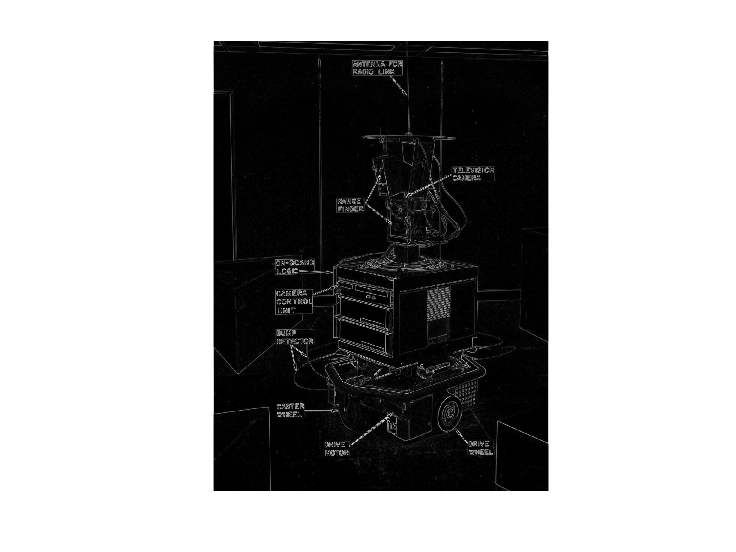

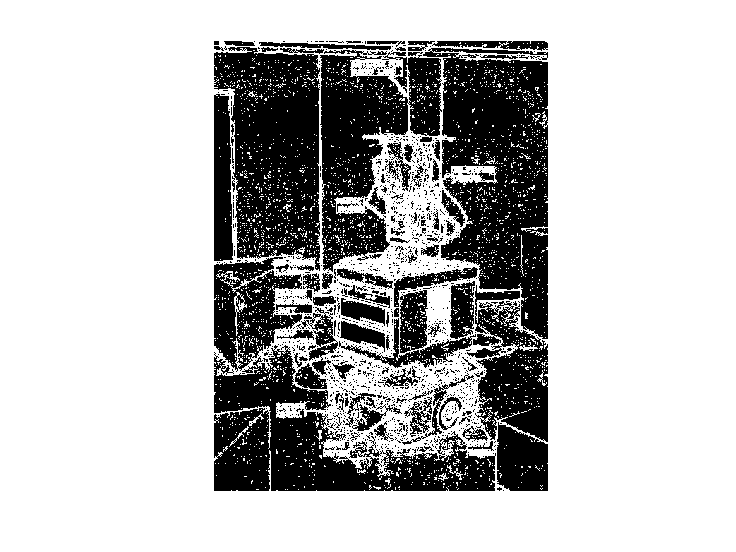

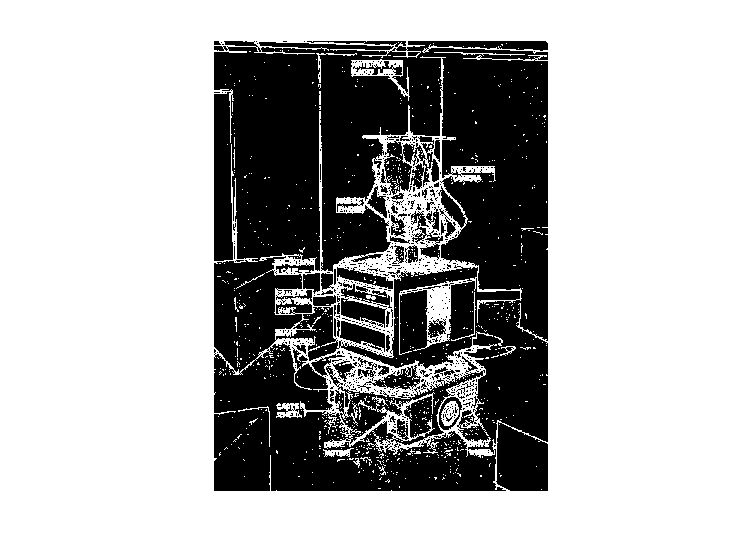

i = 2

d = 86.5098

mean_last = 148.0942

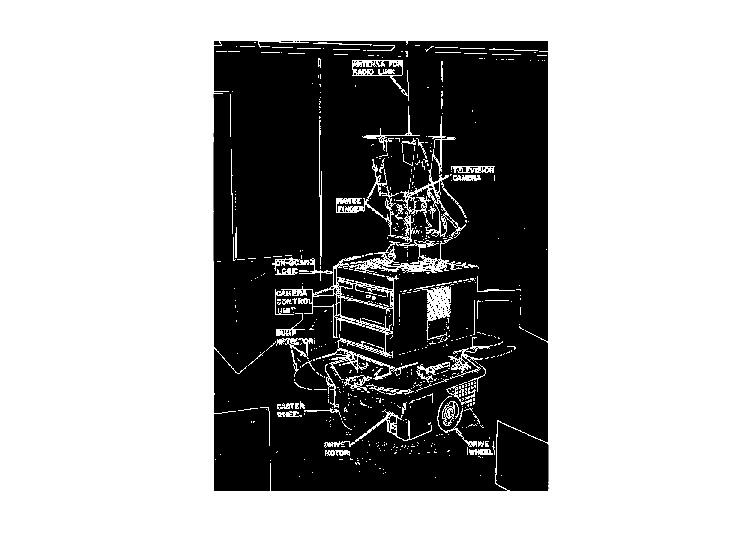

i = 3

d = 76.8796

mean_last = 224.9738

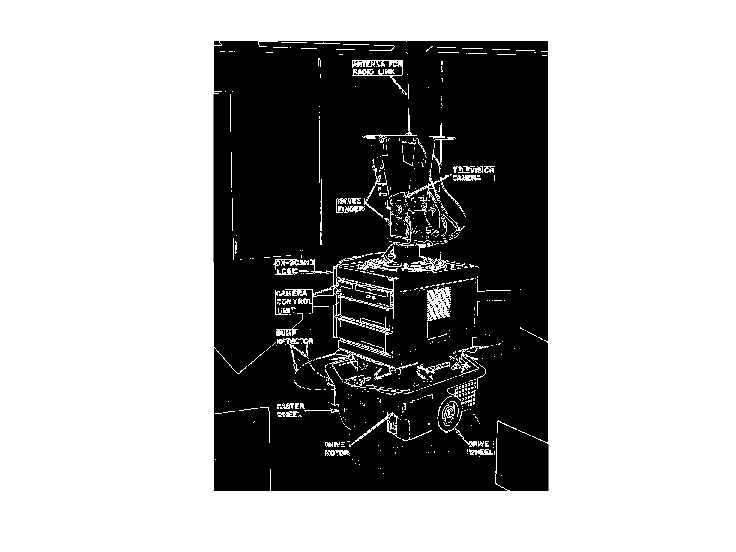

i = 4

d = 41.6957

mean_last = 266.6695

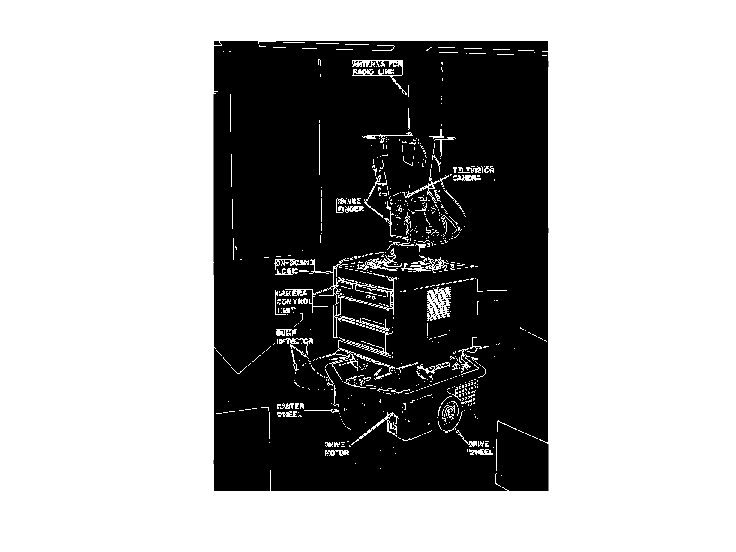

im_app = task1(shakey, sobelX, sobelY, 1, 50, 'sobel-appr-');

im_diff = im_sol - im_app

im_diff = im_diff(:,:,1) =

  Columns 1 through 999

   -3.8341    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.1153    3.1026    3.1934    3.1934    3.1934    3.1934    3.1934    3.1934    2.6145    2.9815    2.9876   -0.3405   -1.5523   -0.1817    1.5893    1.3730    0.3312    0.7559    0.7663    0.9336    1.4573    0.9233    0.5247    0.4821   -0.0426   -0.1439    0.3386    0.6395    0.4464    0.5123    0.5421    0.1736    0.6773    0.5033    0.4554    0.4243    0.4891    0.6203    0.4891    0.4959    0.6970    0.5948    0.6843    0.6843    0.6843    0.6843    0.6843    0.6843    0.4834    0.4583    0.6336    0.6336    0.6336    0.6336    0.6336    0.6336    0.6336    0.6336    0.5822    0.5253    0.5632    0.5568    0.5000    0.5378    0.4937    0.5063    0.5568    0.5000    0.5378    0.5315    0.4748    0.5125    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.3651    0.3838    0.5956    0.5956    0.5956    0.5956    0.5956    0.5

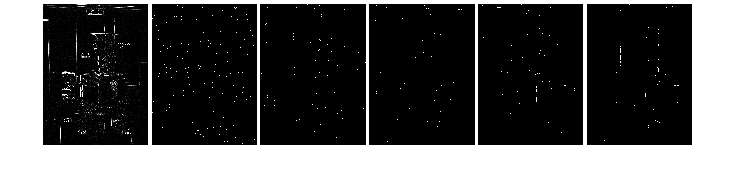

show_images(im_diff) 

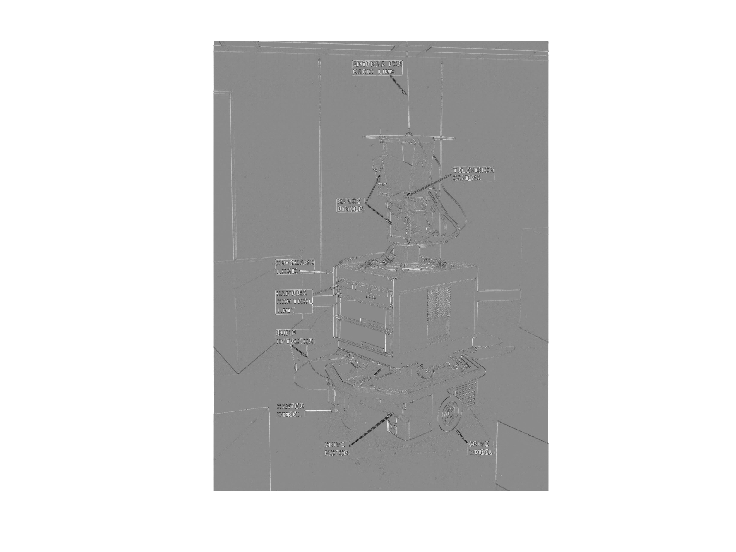

ans =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


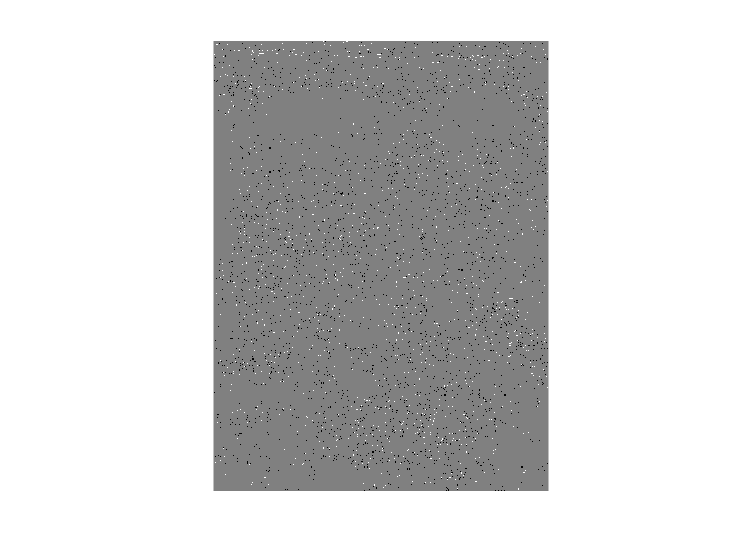

ans =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


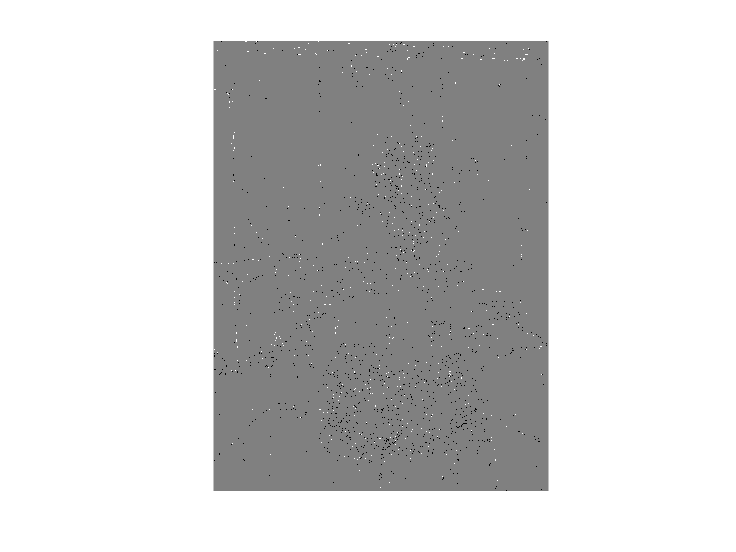

ans =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


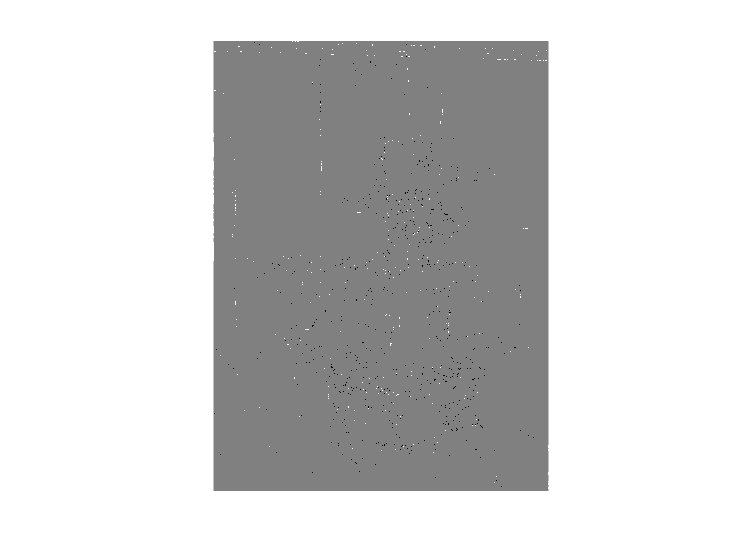

ans =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


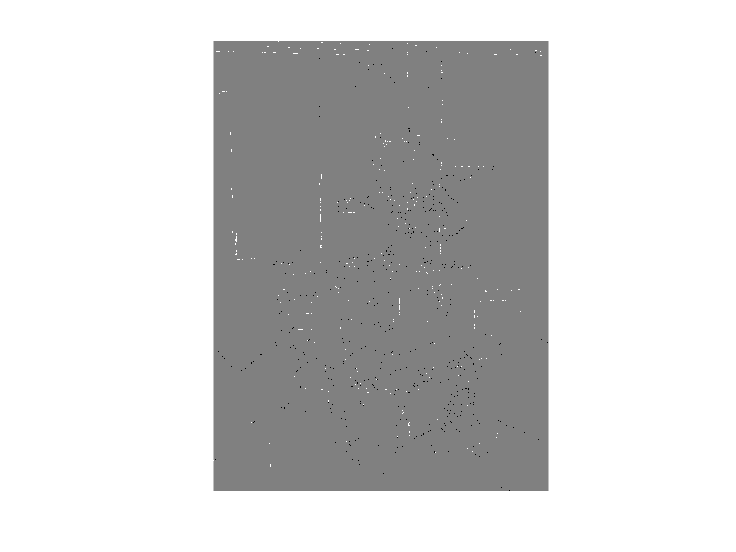

ans =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


for i=[1 2 3 4 5]
    show_image(im_diff(:,:,i), ['sobel-diff-', num2str(i)])
end

im_diff2 = im_rob - im_app

im_diff2 = im_diff2(:,:,1) =

  Columns 1 through 999

  -24.7465  -16.4977  -16.4977  -16.4977  -16.4977  -16.4977  -16.4977  -16.3012  -16.4977  -16.3678  -16.3678  -16.3678  -16.3678  -16.3678  -16.3678  -15.2201  -14.2761  -14.1112  -10.9123  -11.0745  -10.6553   -7.9723   -7.1828   -6.5414   -7.1416   -6.6361   -7.1080   -7.1771   -6.8720   -6.4955   -6.2735   -4.4633   -4.9703   -3.8869   -3.7757   -3.6948   -4.0594   -3.5240   -3.5969   -2.7546   -3.5962   -3.5698   -3.4663   -3.3874   -3.1708   -3.3109   -3.4408   -3.3109   -3.6373   -3.5074   -3.5074   -3.5074   -3.5074   -3.5074   -3.5074   -3.1143   -3.5074   -3.2476   -3.2476   -3.2476   -3.2476   -3.2476   -3.2476   -3.2476   -3.2476   -3.1493   -3.1493   -3.1826   -3.0194   -3.0194   -3.0527   -2.8562   -3.1826   -3.0194   -3.0194   -3.0527   -2.8895   -2.8895   -2.9228   -2.8579   -2.8579   -2.8579   -2.8579   -2.8579   -2.8579   -2.8579   -2.8579   -2.5786   -2.9536   -2.7912   -2.7912   -2.7912   -2.7912   -2.7912   -2

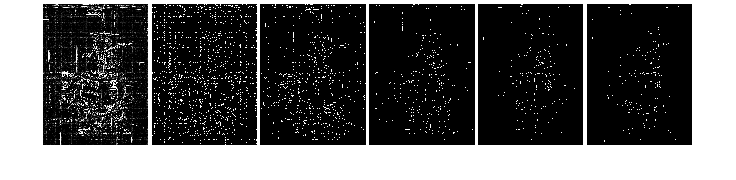

show_images(im_diff2)

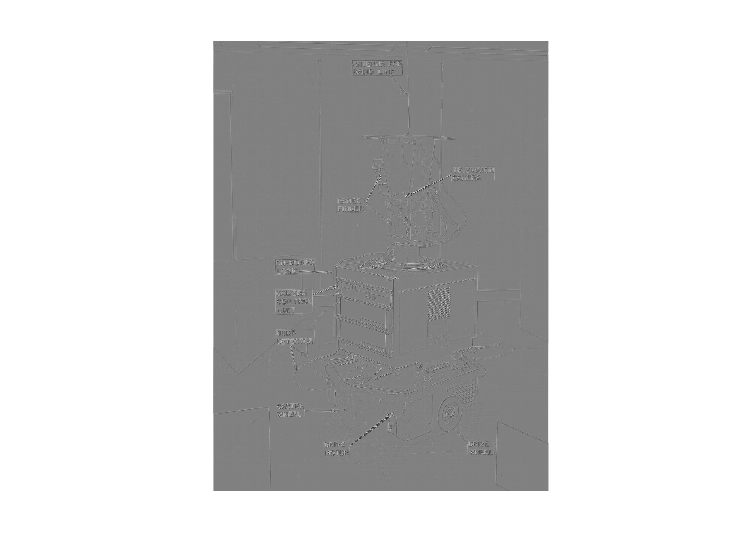

ans =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


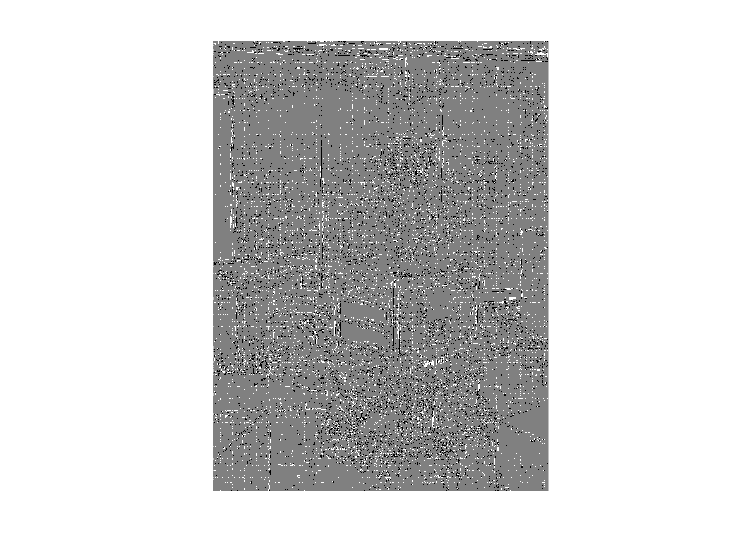

ans =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


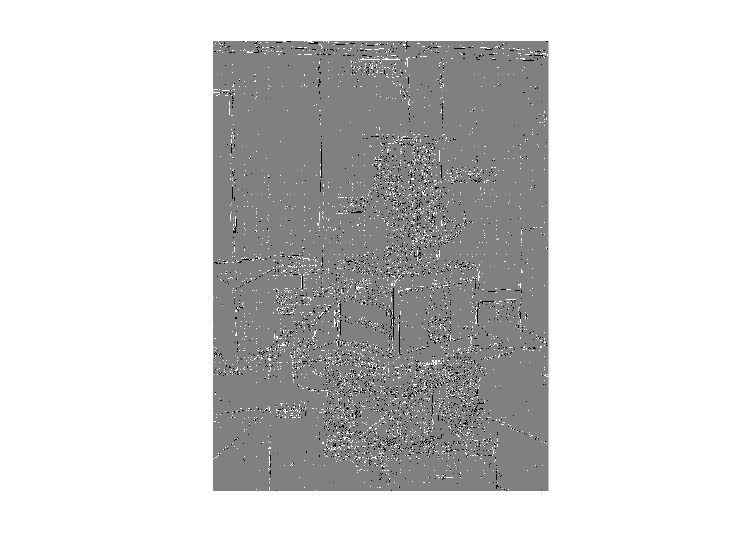

ans =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


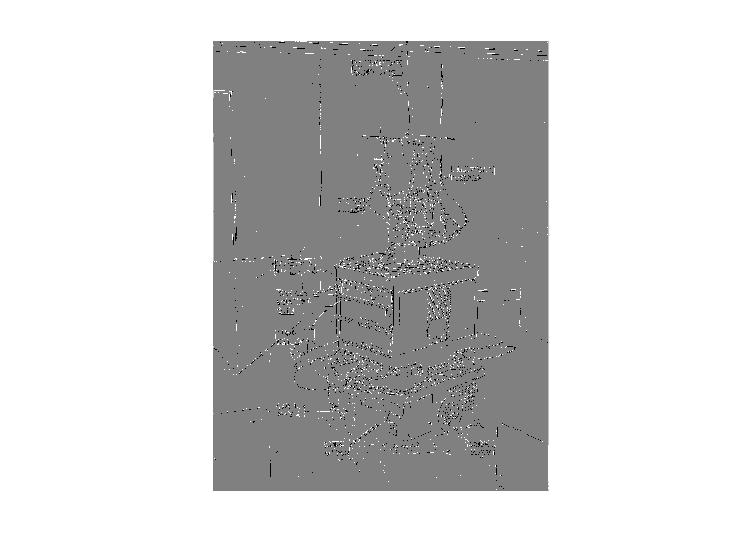

ans =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


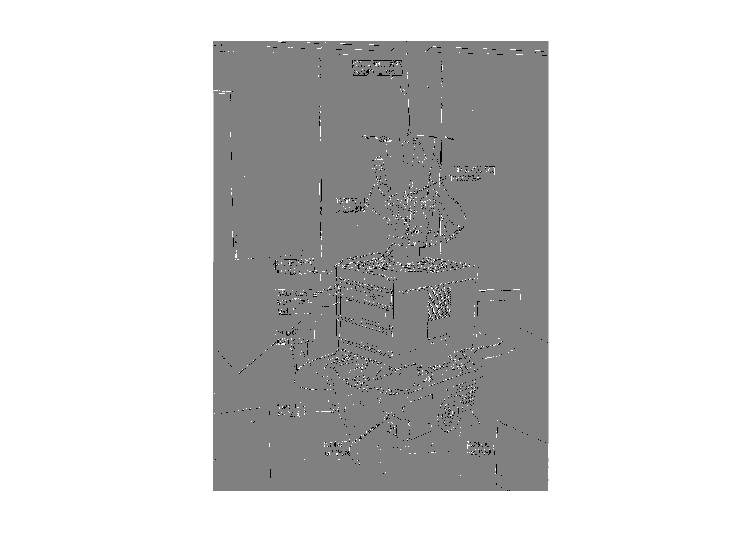

ans =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties



for i=[1 2 3 4 5]
    show_image(im_diff2(:,:,i), ['rob-diff-', num2str(i)])
end

**QUESTION 3: What do you notice regarding the difference between magnitude and absolute when calculating the edge? **

**Denoising:**

gaussian5 = conv_gaussian(5, 1.4)

gaussian5 =     0.0121    0.0261    0.0337    0.0261    0.0121
    0.0261    0.0561    0.0724    0.0561    0.0261
    0.0337    0.0724    0.0935    0.0724    0.0337
    0.0261    0.0561    0.0724    0.0561    0.0261
    0.0121    0.0261    0.0337    0.0261    0.0121


i = 1

d = 10000

mean_last = 35.7692

new_im =   701.7451  799.5468  881.2649  904.0272  904.0272  903.8312  903.0185  901.4369  899.5055  897.9201  897.1051  896.9089  896.9089  895.8855  892.8797  888.8661  880.7861  856.0887  801.2282  713.6037  608.5934  516.2161  455.4718  420.5103  400.6485  392.4652  394.0230  398.2336  396.3434  382.9686  357.7793  324.6980  289.7496  258.9039  237.0152  225.2544  219.4613  214.8259  209.7787  205.3106  202.1933  199.1793  194.8956  190.2871  187.9718  188.7953  191.0478  192.7862  193.2258  192.8015
  799.5468  427.9920  356.1641  352.6754  352.6754  352.5997  352.2895  351.6834  350.9300  350.3006  349.9758  349.8984  349.8984  349.8506  349.6206  349.6186  352.4389  364.2344  387.6564  398.3795  363.4212  291.1882  222.9828  180.7889  159.2302  148.5842  145.6685  148.6842  156.1745  164.9379  169.6489  166.9104  156.9912  141.0327  121.0440  102.0364   88.6245   81.8710   79.9547   80.0358   80.3706   80.3468   80.0945   79.1781   77.8892   76.8382   75.8373   75.0873   74.8514

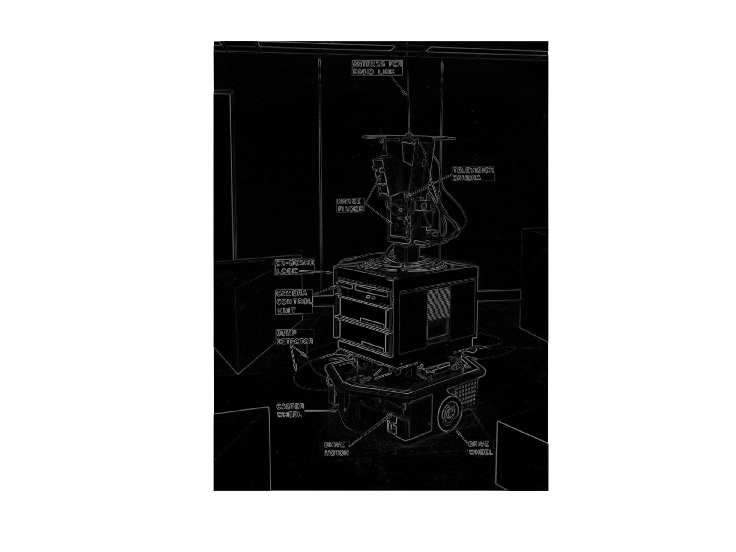

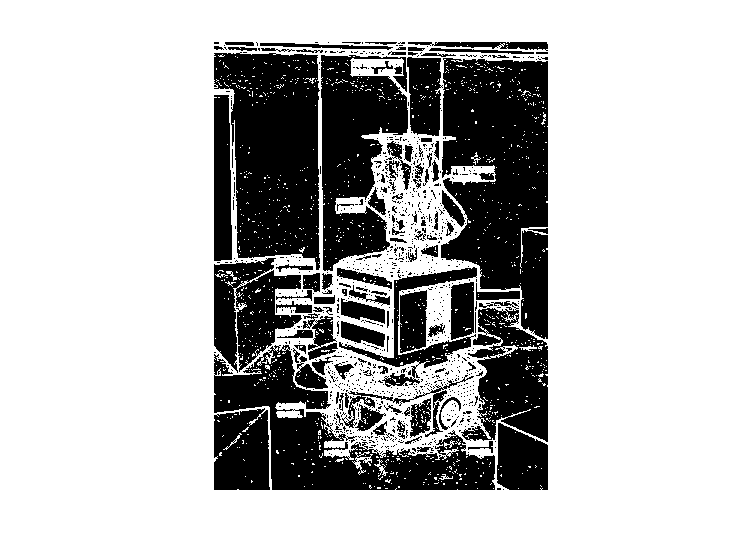

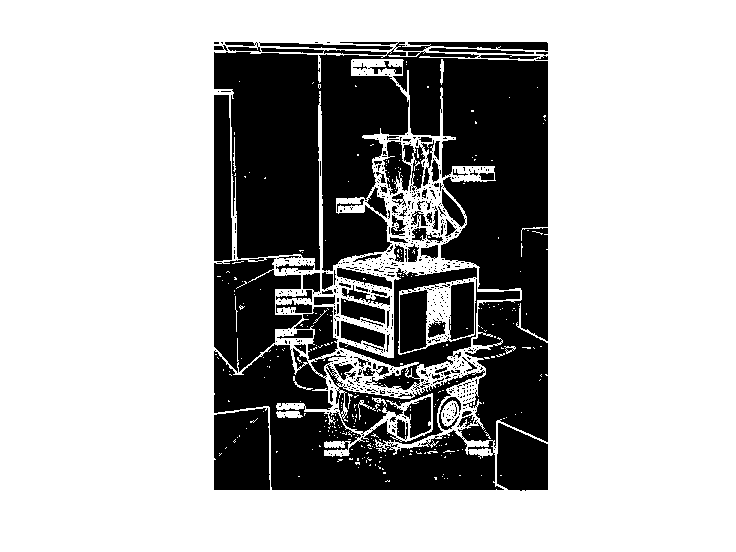

i = 2

d = 44.8232

mean_last = 80.5925

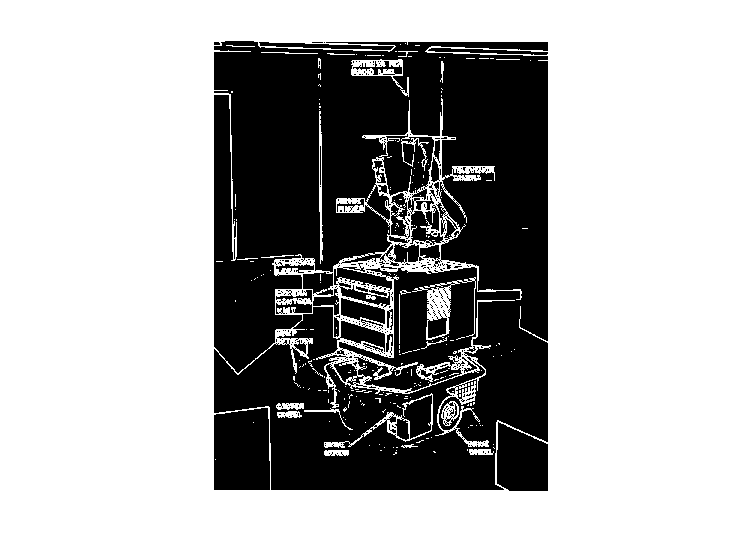

% round(gaussian5 * 159)
shakey_smooth = conv2(shakey, gaussian5, "same");
im_g5 = task1(shakey_smooth, sobelX, sobelY, 0, 50, 'gaussian5-');

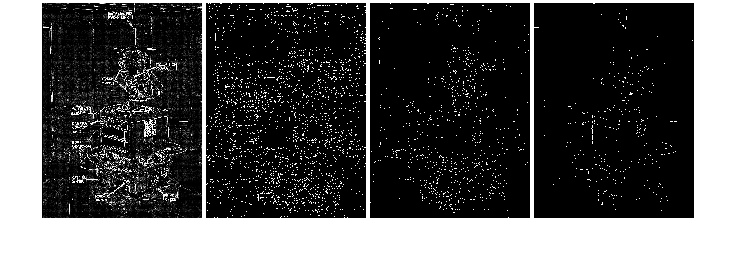


im_diff5 = im_sol(:,:,1:4) - im_g5;
show_images(im_diff5)

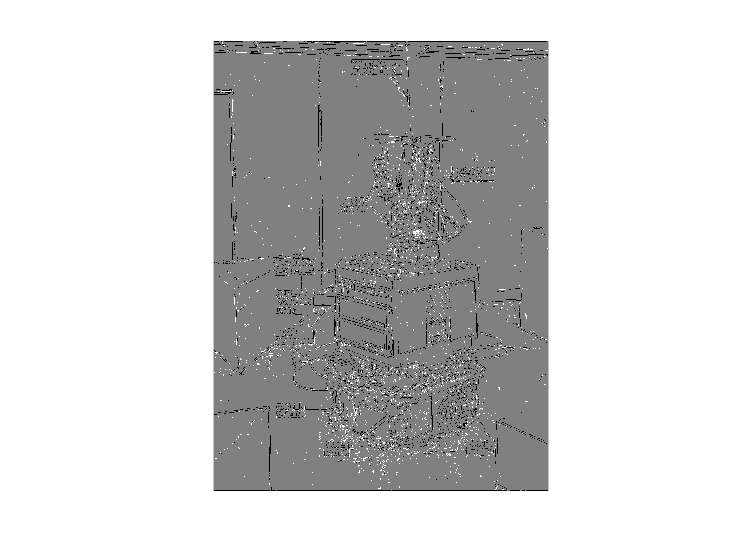

show_image(im_diff5(:,:,3), ['g5-diff-mean']);


gaussian3 = conv_gaussian(3, 1)

gaussian3 =     0.0751    0.1238    0.0751
    0.1238    0.2042    0.1238
    0.0751    0.1238    0.0751


% gaussian5 .* 256
shakey_smooth = conv2(shakey, gaussian3, "same");

i = 1

d = 10000

mean_last = 42.5790

new_im = 	1.0e+03 *

    0.8807    0.9617    1.0160    1.0160    1.0160    1.0160    1.0155    1.0135    1.0106    1.0085    1.0080    1.0080    1.0080    1.0080    1.0049    0.9974    0.9918    0.9770    0.9190    0.7987    0.6466    0.5428    0.4969    0.4685    0.4442    0.4361    0.4447    0.4542    0.4525    0.4340    0.4009    0.3594    0.3156    0.2775    0.2541    0.2470    0.2477    0.2451    0.2360    0.2284    0.2273    0.2253    0.2183    0.2108    0.2080    0.2105    0.2153    0.2180    0.2177    0.2165
    0.9617    0.3668    0.2785    0.2785    0.2785    0.2785    0.2783    0.2778    0.2770    0.2764    0.2763    0.2763    0.2763    0.2763    0.2762    0.2754    0.2765    0.2941    0.3673    0.4307    0.3667    0.2408    0.1593    0.1351    0.1258    0.1125    0.1054    0.1100    0.1281    0.1474    0.1550    0.1546    0.1489    0.1325    0.1057    0.0798    0.0637    0.0597    0.0631    0.0634    0.0638    0.0641    0.0655    0.0643    0.0628    0.0618    0.0601    0.05

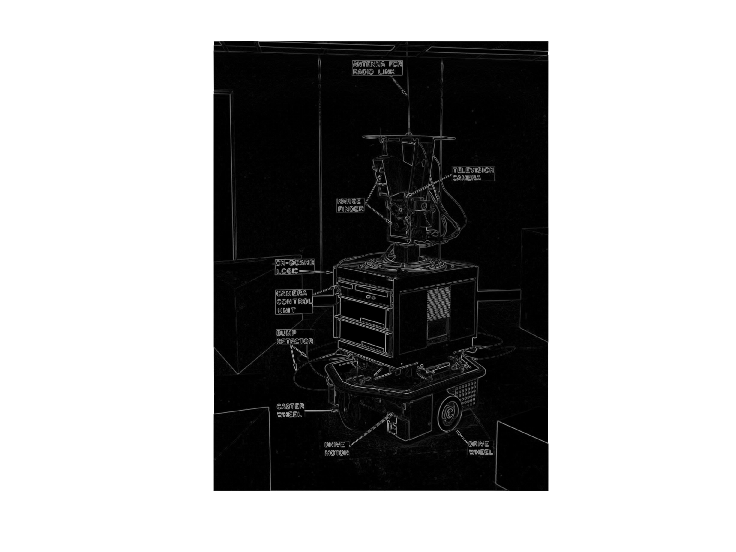

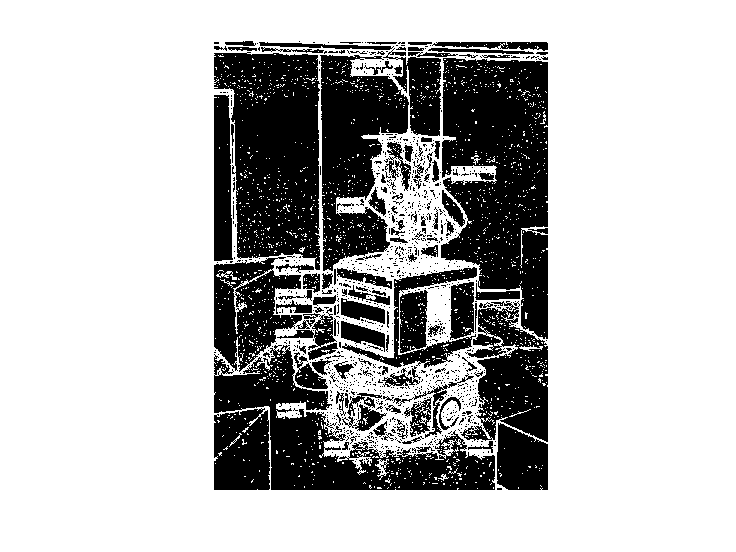

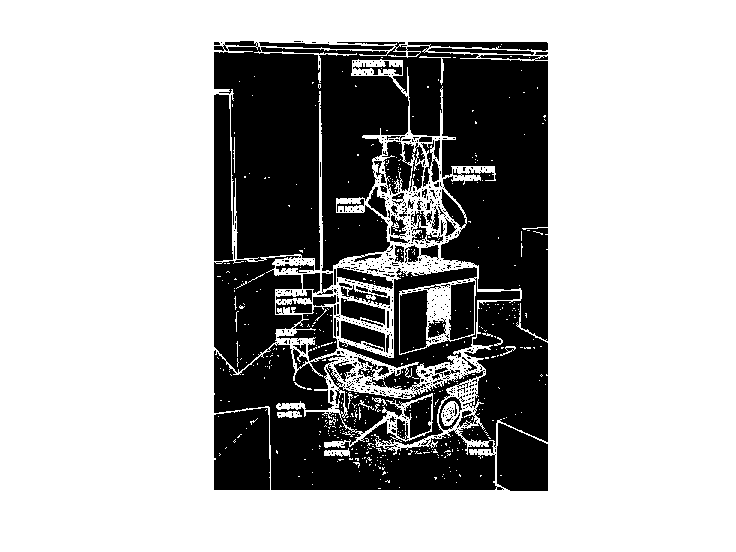

i = 2

d = 60.0314

mean_last = 102.6104

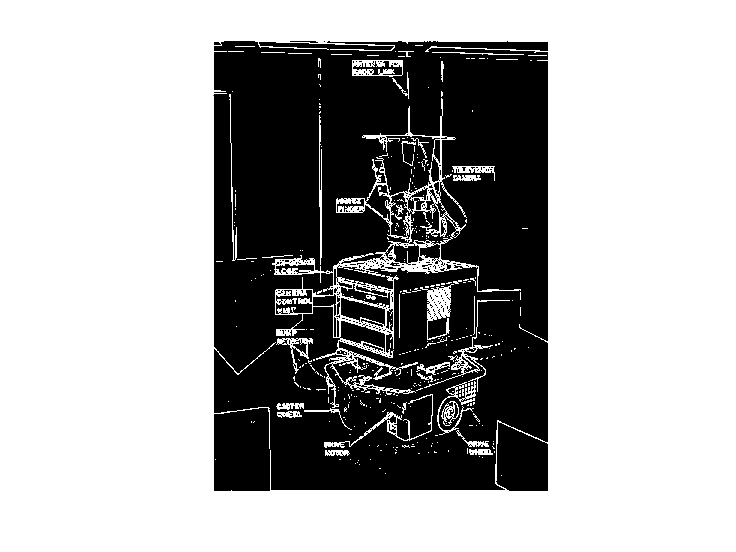

i = 3

d = 42.0365

mean_last = 144.6469

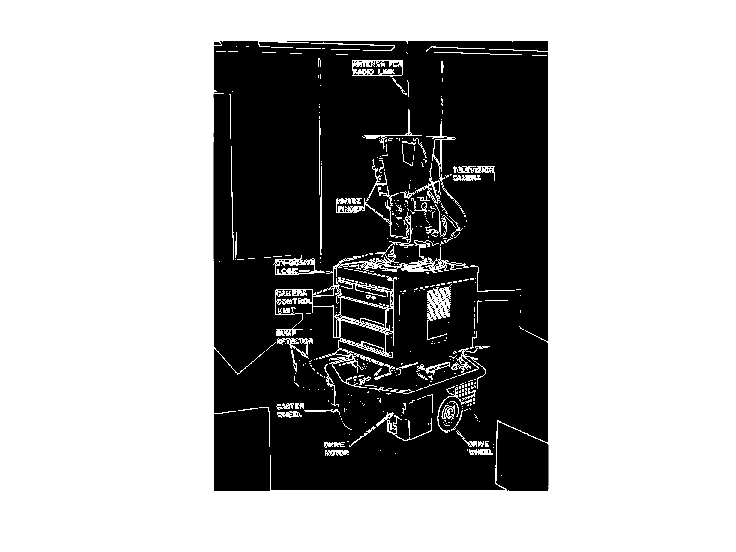


im_g3 = task1(shakey_smooth, sobelX, sobelY, 0, 50, 'gaussian3-');

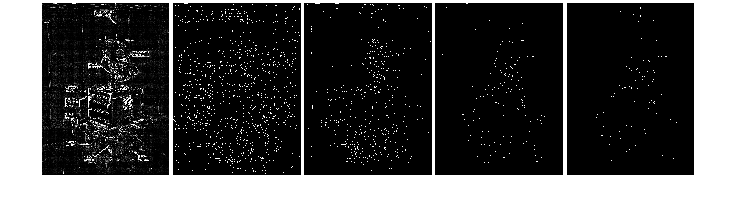


im_diff3 = im_sol(:,:,1:5) - im_g3;
show_images(im_diff3)

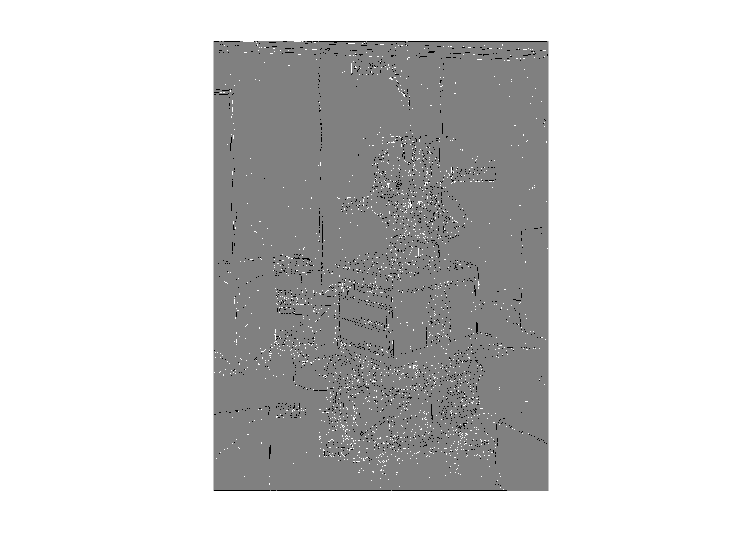

show_image(im_diff3(:,:,3), ['g3-diff-mean']);

**Other filters:**

**Laplacian:**

laplacian = [0 -1 0 ; -1 4 -1; 0 -1 0]

laplacian =      0    -1     0
    -1     4    -1
     0    -1     0


laplacian_diagonal = [-1 -1 -1; -1 8 -1; -1 -1 -1]

laplacian_diagonal =     -1    -1    -1
    -1     8    -1
    -1    -1    -1


laplacian_gaussian = [0 0 -1 0 0; 0 -1 -2 -1 0; -1 -2 16 -2 -1; 0 -1 -2 -1 0; 0 0 -1 0 0]

laplacian_gaussian =      0     0    -1     0     0
     0    -1    -2    -1     0
    -1    -2    16    -2    -1
     0    -1    -2    -1     0
     0     0    -1     0     0


save("laplacian.mat", "laplacian", "laplacian_diagonal", "laplacian_gaussian");

i = 1

d = 10000

mean_last = 0.2866

new_im =   166.6349  165.3077  114.7731  114.7731  114.7731  114.7731  115.1711  114.7836  113.8590  113.4715  113.8694  113.8694  113.8694  113.8694  116.1330  111.0887  112.1294  123.8695  112.6202   64.2756   34.2544   44.9161   62.4923   55.7181   42.7790   44.9447   56.2378   58.5145   54.1829   46.6236   43.3318   36.7080   26.3548   19.0395   20.6262   24.7469   31.5474   33.0321   25.7890   22.6398   26.1837   27.7417   23.7814   21.7605   21.3034   22.6036   25.1213   25.8470   24.8632   24.0027
  165.3077  139.2269   69.6134   69.6134   69.6134   69.6134   70.1616   69.8188   68.8599   68.5172   69.0653   69.0653   69.0653   69.0653   72.2039   65.7662   65.6328   82.3721   82.6396   41.3659    8.8865   13.4708   32.0104   32.4418   23.9629   24.3541   33.1264   36.8024   36.3819   31.1632   27.0185   20.9894   14.0933    9.0367    9.4061   12.5062   19.2318   21.5309   15.1066   12.4924   16.1113   17.7486   13.9407   12.2081   11.7826   12.9946   15.6219   16.3383   15.2399

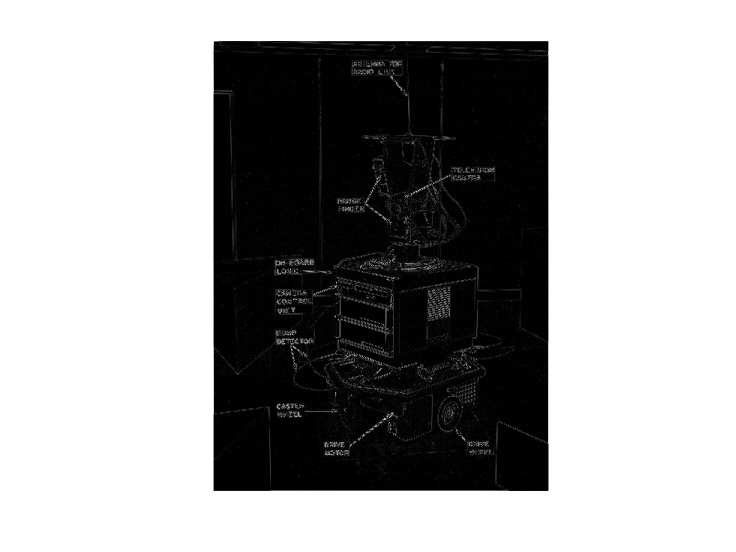

load("laplacian.mat");
im_lap = task1(shakey_smooth, laplacian, laplacian, -1, 0, 'laplacian-');

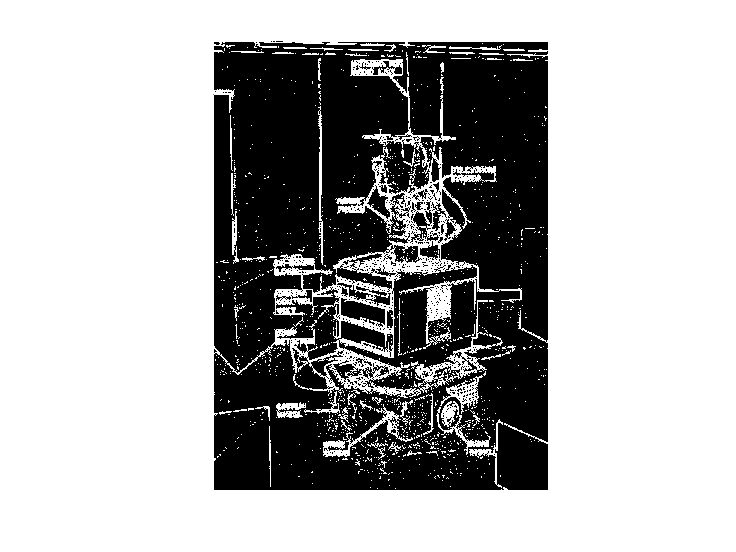

ans =   Figure (46) with properties:

      Number: 46
        Name: ''
       Color: [1 1 1]
    Position: [620 647 560 420]
       Units: 'pixels'

  Show all properties


show_image(abs(im_lap) >20, 'diff_lap')

i = 1

mean_last = 1.8282

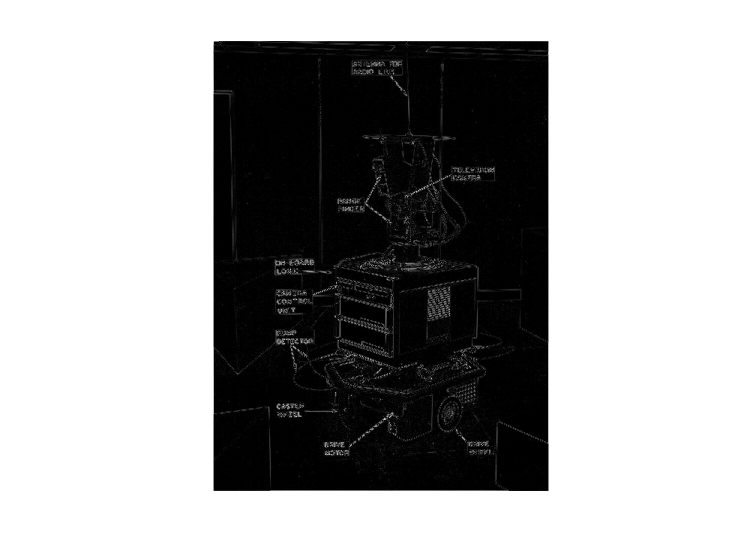

img3 =   427.3661  508.1132  341.5374  313.8958  313.8958  314.1134  315.2074  314.0541  311.2658  310.1126  311.2065  311.4242  311.4242  312.6623  317.3322  304.5491  312.3594  348.1437  311.1051  166.5075   73.6326  105.9994  164.1311  151.4818  114.8320  120.7350  154.7737  164.7340  151.6055  129.4616  117.3270   96.7640   65.6763   44.5101   49.2909   65.3503   87.5372   92.0459   71.2084   61.2239   71.2670   76.0600   65.0799   57.8601   56.4774   61.0142   68.9073   71.4340   68.4045   65.6809
  508.1132  572.0523  329.3216  291.2441  291.2441  291.5439  293.1553  291.8346  288.3603  287.0395  288.6510  288.9508  288.9508  290.6676  297.4468  278.3002  283.5087  338.6203  328.7513  180.4604   55.7284   60.9668  122.2933  129.8034  103.7687  104.9956  135.0239  151.9433  150.9217  132.2994  112.9197   87.8648   60.2799   40.6131   40.2343   53.4214   77.6880   85.3533   64.7083   55.0528   66.4710   71.7727   59.3987   51.5656   49.9587   55.0032   64.3885   67.4549   63.8224  


img3 = task1(shakey_smooth, laplacian_gaussian, 0, -1, 0, 'lapgaussian-')

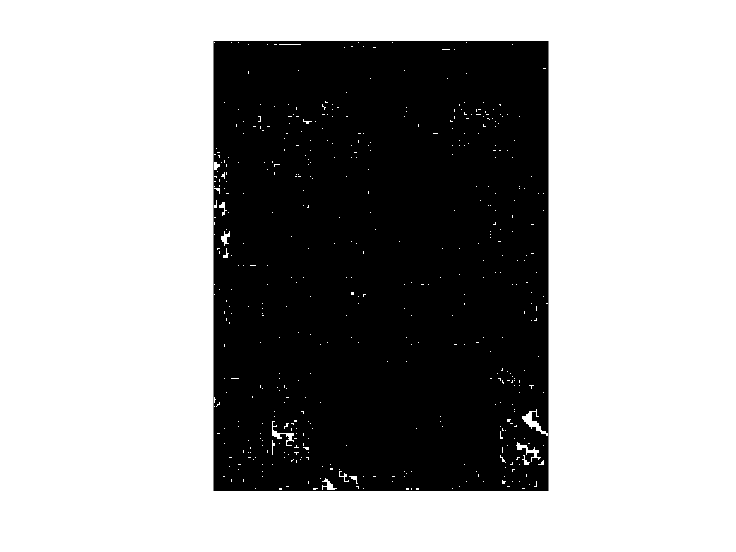

Not enough input arguments.

Error in show_image (line 12)
if file_name

show_image(abs(img3)==0)